# RVC2: Chapter 16 - Advanced Visual Servoing

## 16.1 XY/Z partitioned IBVS

principal point not specified, setting it to centre of image plane
 
cam = 
 
name: default [central-perspective]                     
  focal length:   0.008                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1024 x 1024                           
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg
 
delete camera object
creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes

Simulink.SimulationOutput:

    tout: [8001x1 double]
    yout: [1x1 struct]

Use get to access a variable by name.
Use getSimulationMetadata to access metadata about the simulation.



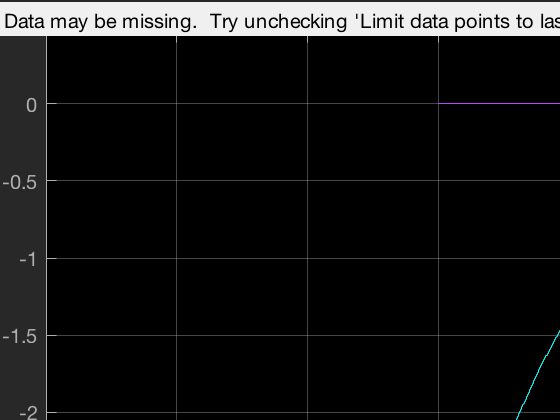

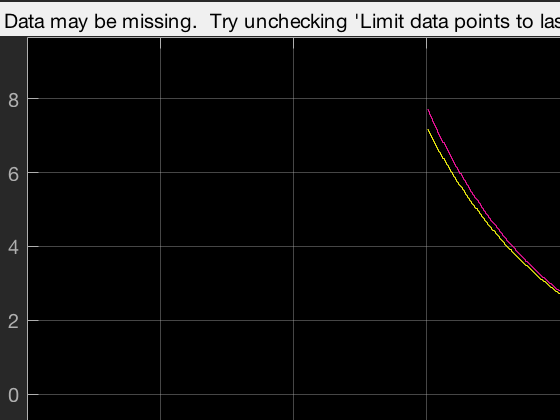

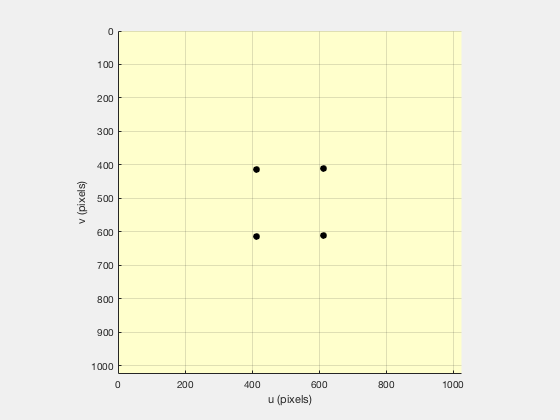

sl_partitioned
sim('sl_partitioned')

## 16.2 IBVS polar

cam = CentralCamera('default')

principal point not specified, setting it to centre of image plane
 
cam = 
 
name: default [central-perspective]                     
  focal length:   0.008                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1024 x 1024                           
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg
 


T_C0 = SE3(-0.3, 0.2, -2)*SE3.Rz(pi/2);
vs = IBVS_polar(cam, 'T0', T_C0)

 
vs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( -0.3,  0.2,  -2), R = ( 90deg |  0,  0,  1) 


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes
v: 0.552 -0.771 0.061 0.000 -0.001 -0.042
v: 0.043 -0.301 0.056 0.001 -0.001 -0.032
v: -2.167 1.183 0.057 0.002 0.001 0.005
v: -2.232 1.084 0.060 0.002 0.001 0.006
v: -2.275 0.972 0.064 0.002 0.001 0.006
v: -2.291 0.849 0.067 0.002 0.001 0.005
v: -2.281 0.718 0.070 0.002 0.001 0.004
v: -2.242 0.583 0.073 0.002 0.001 0.003
v: -2.176 0.446 0.076 0.002 0.001 0.001
v: -2.085 0.311 0.078 0.002 0.001 -0.001
v: -1.970 0.180 0.080 0.002 0.001 -0.003
v: -1.834 0.058 0.081 0.002 0.001 -0.005
v: -1.682 -0.054 0.082 0.001 0.001 -0.008
v: -1.515 -0.154 0.083 0.001 0.001 -0.011
v: -1.340 -0.240 0.083 0.001 0.001 -0.013
v: -1.162 -0.311 0.084 0.001 0.001 -0.016
v: -0.984 -0.366 0.083 0.001 0.001 -0.019
v: -0.814 -0.406 0.083 0.001 0.000 -0.021
v: -0.656 -0.431 0.082 0.001 0.000 -0.023
v: -0.515 -0.443 0.081 0.001 0.000 -0.025
v: -0.396 -0.445 0.079 0.001 0.000 -0.027
v: -0.299 -0.438 0.078 0.001 0.000 -0.028
v: -0.223 -0.427 0.076 0.001 0.000 -0.029
v: -0.166 -0.411 0.074 0.001 0.000 -0.030

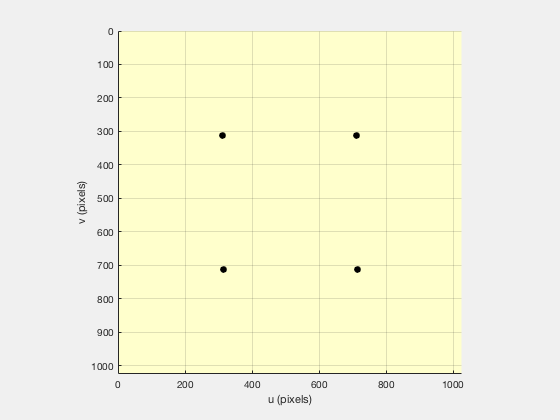

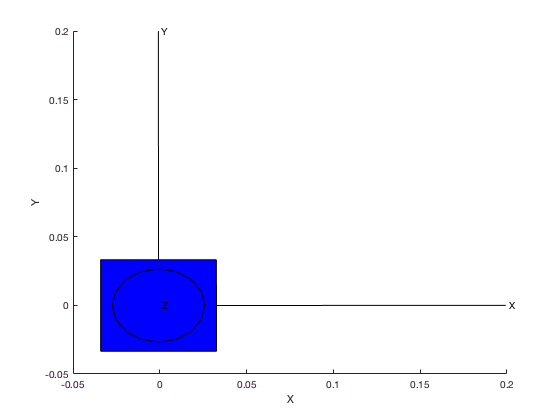


vs.run()

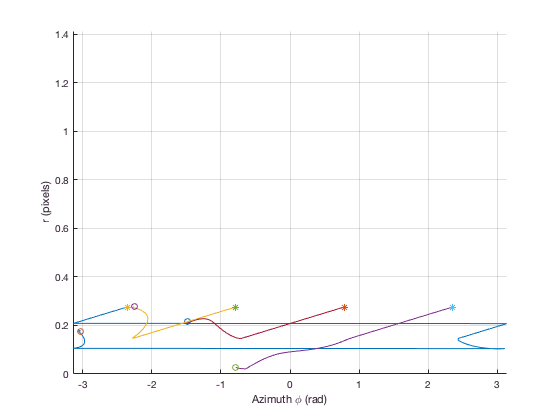


vs.plot_features()

## 16.3 IBVS spherical

cam = SphericalCamera()

principal point not specified, setting it to centre of image plane
 
cam = 
 
name: spherical-default [spherical]                     
  pixel size:     (1, 1)                                
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg
 



T_C0 = SE3(0.3, 0.3, -2)*SE3.Rz(0.4);

vs = IBVS_sph(cam, 'T0', T_C0, 'verbose')

delete camera object


 
vs = 
Visual servo object: camera=spherical-default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                        
     -0.25        0.25        0.25       -0.25                        
         0           0           0           0                        
  C_T0:   t = ( 0.3,  0.3,  -2), R = ( 22.9183deg |  0,  0,  1)       


vs.run()

ans = []

ans = 

ans =      2     2     2     2


v: -0.955 -0.313 -0.160 -0.163 0.480 0.002


ans =     2.0299    2.1802    2.3490    2.1987


v: -0.453 -0.227 0.040 -0.108 0.196 0.007


ans =     1.8833    2.1058    2.3322    2.1097


v: -0.259 -0.141 0.077 -0.071 0.110 0.012


ans =     1.7397    2.0025    2.2548    1.9919


v: -0.163 -0.100 0.080 -0.053 0.068 0.010


ans =     1.6160    1.9056    2.1694    1.8797


v: -0.107 -0.075 0.076 -0.042 0.043 0.007


ans =     1.5117    1.8205    2.0884    1.7796


v: -0.072 -0.058 0.069 -0.033 0.027 0.003


ans =     1.4240    1.7470    2.0150    1.6920


v: -0.049 -0.046 0.062 -0.027 0.017 -0.001


ans =     1.3498    1.6836    1.9496    1.6158


v: -0.034 -0.037 0.055 -0.022 0.010 -0.004


ans =     1.2866    1.6288    1.8918    1.5496


v: -0.024 -0.031 0.049 -0.018 0.005 -0.006


ans =     1.2322    1.5810    1.8405    1.4917


v: -0.017 -0.026 0.043 -0.015 0.002 -0.008


ans =     1.1851    1.5392    1.7950    1.4410


v: -0.012 -0.022 0.039 -0.012 -0.001 -0.009


ans =     1.1440    1.5023    1.7545    1.3962


v: -0.008 -0.019 0.035 -0.010 -0.002 -0.010


ans =     1.1079    1.4696    1.7182    1.3565


v: -0.006 -0.016 0.031 -0.008 -0.003 -0.011


ans =     1.0760    1.4405    1.6855    1.3211


v: -0.003 -0.014 0.028 -0.007 -0.004 -0.011


ans =     1.0478    1.4145    1.6561    1.2894


v: -0.001 -0.012 0.026 -0.006 -0.005 -0.012


ans =     1.0228    1.3912    1.6295    1.2610


v: 0.000 -0.010 0.023 -0.004 -0.006 -0.012


ans =     1.0004    1.3702    1.6052    1.2355


v: 0.001 -0.009 0.021 -0.003 -0.007 -0.012


ans =     0.9806    1.3513    1.5832    1.2124


v: 0.002 -0.007 0.019 -0.002 -0.007 -0.012


ans =     0.9629    1.3343    1.5630    1.1916


v: 0.003 -0.006 0.018 -0.002 -0.008 -0.012


ans =     0.9471    1.3190    1.5446    1.1727


v: 0.004 -0.005 0.016 -0.001 -0.008 -0.012


ans =     0.9331    1.3052    1.5276    1.1556


v: 0.005 -0.004 0.015 -0.000 -0.009 -0.012


ans =     0.9207    1.2927    1.5120    1.1400


v: 0.006 -0.003 0.013 0.001 -0.009 -0.012


ans =     0.9098    1.2814    1.4976    1.1259


v: 0.007 -0.002 0.012 0.001 -0.009 -0.012


ans =     0.9002    1.2713    1.4843    1.1131


v: 0.007 -0.002 0.011 0.002 -0.010 -0.012


ans =     0.8917    1.2622    1.4719    1.1015


v: 0.008 -0.001 0.010 0.002 -0.010 -0.012


ans =     0.8844    1.2539    1.4604    1.0909


v: 0.009 -0.000 0.009 0.003 -0.010 -0.012


ans =     0.8782    1.2465    1.4497    1.0813


v: 0.009 0.000 0.009 0.003 -0.011 -0.012


ans =     0.8728    1.2399    1.4396    1.0726


v: 0.009 0.001 0.008 0.004 -0.011 -0.012


ans =     0.8683    1.2339    1.4302    1.0646


v: 0.010 0.002 0.007 0.004 -0.011 -0.011


ans =     0.8645    1.2284    1.4213    1.0574


v: 0.010 0.002 0.007 0.005 -0.011 -0.011


ans =     0.8615    1.2235    1.4129    1.0508


v: 0.011 0.003 0.006 0.005 -0.011 -0.011


ans =     0.8590    1.2191    1.4049    1.0448


v: 0.011 0.003 0.006 0.006 -0.012 -0.011


ans =     0.8572    1.2151    1.3972    1.0393


v: 0.011 0.004 0.005 0.006 -0.012 -0.011


ans =     0.8558    1.2114    1.3899    1.0343


v: 0.011 0.004 0.005 0.007 -0.012 -0.011


ans =     0.8549    1.2080    1.3828    1.0297


v: 0.011 0.004 0.005 0.007 -0.012 -0.010


ans =     0.8544    1.2049    1.3760    1.0255


v: 0.011 0.005 0.004 0.007 -0.012 -0.010


ans =     0.8543    1.2021    1.3695    1.0217


v: 0.011 0.005 0.004 0.008 -0.012 -0.010


ans =     0.8545    1.1994    1.3630    1.0181


v: 0.011 0.006 0.004 0.008 -0.011 -0.010


ans =     0.8549    1.1969    1.3568    1.0148


v: 0.011 0.006 0.004 0.008 -0.011 -0.010


ans =     0.8557    1.1945    1.3507    1.0118


v: 0.011 0.006 0.003 0.008 -0.011 -0.009


ans =     0.8566    1.1923    1.3447    1.0090


v: 0.011 0.006 0.003 0.008 -0.011 -0.009


ans =     0.8578    1.1901    1.3388    1.0064


v: 0.011 0.007 0.003 0.009 -0.011 -0.009


ans =     0.8591    1.1880    1.3330    1.0040


v: 0.011 0.007 0.003 0.009 -0.011 -0.009


ans =     0.8605    1.1860    1.3272    1.0018


v: 0.011 0.007 0.003 0.009 -0.011 -0.008


ans =     0.8621    1.1840    1.3216    0.9997


v: 0.011 0.007 0.003 0.009 -0.010 -0.008


ans =     0.8638    1.1821    1.3160    0.9977


v: 0.011 0.007 0.003 0.009 -0.010 -0.008


ans =     0.8656    1.1801    1.3104    0.9958


v: 0.011 0.007 0.002 0.009 -0.010 -0.008


ans =     0.8674    1.1783    1.3049    0.9941


v: 0.010 0.008 0.002 0.009 -0.010 -0.007


ans =     0.8694    1.1764    1.2995    0.9925


v: 0.010 0.008 0.002 0.009 -0.010 -0.007


ans =     0.8714    1.1745    1.2941    0.9909


v: 0.010 0.008 0.002 0.009 -0.010 -0.007


ans =     0.8734    1.1726    1.2887    0.9895


v: 0.010 0.008 0.002 0.009 -0.009 -0.007


ans =     0.8755    1.1707    1.2833    0.9881


v: 0.010 0.008 0.002 0.009 -0.009 -0.006


ans =     0.8776    1.1688    1.2781    0.9868


v: 0.010 0.008 0.002 0.009 -0.009 -0.006


ans =     0.8797    1.1669    1.2728    0.9855


v: 0.009 0.008 0.002 0.009 -0.009 -0.006


ans =     0.8818    1.1650    1.2676    0.9844


v: 0.009 0.008 0.002 0.009 -0.008 -0.006


ans =     0.8840    1.1631    1.2624    0.9833


v: 0.009 0.008 0.002 0.009 -0.008 -0.006


ans =     0.8861    1.1612    1.2573    0.9822


v: 0.009 0.008 0.002 0.009 -0.008 -0.005


ans =     0.8883    1.1593    1.2522    0.9812


v: 0.009 0.008 0.002 0.009 -0.008 -0.005


ans =     0.8904    1.1573    1.2471    0.9802


v: 0.008 0.008 0.002 0.009 -0.008 -0.005


ans =     0.8925    1.1553    1.2421    0.9793


v: 0.008 0.008 0.002 0.009 -0.007 -0.005


ans =     0.8947    1.1534    1.2372    0.9785


v: 0.008 0.008 0.002 0.009 -0.007 -0.005


ans =     0.8968    1.1514    1.2323    0.9777


v: 0.008 0.008 0.002 0.009 -0.007 -0.004


ans =     0.8989    1.1494    1.2274    0.9769


v: 0.008 0.008 0.002 0.009 -0.007 -0.004


ans =     0.9010    1.1474    1.2226    0.9762


v: 0.007 0.008 0.002 0.009 -0.007 -0.004


ans =     0.9030    1.1454    1.2179    0.9755


v: 0.007 0.008 0.002 0.009 -0.006 -0.004


ans =     0.9050    1.1434    1.2132    0.9748


v: 0.007 0.008 0.002 0.009 -0.006 -0.004


ans =     0.9071    1.1413    1.2085    0.9742


v: 0.007 0.008 0.002 0.009 -0.006 -0.004


ans =     0.9090    1.1393    1.2039    0.9737


v: 0.007 0.008 0.001 0.009 -0.006 -0.003


ans =     0.9110    1.1373    1.1994    0.9731


v: 0.006 0.008 0.001 0.009 -0.006 -0.003


ans =     0.9129    1.1352    1.1950    0.9726


v: 0.006 0.008 0.001 0.009 -0.006 -0.003


ans =     0.9148    1.1332    1.1906    0.9722


v: 0.006 0.008 0.001 0.009 -0.005 -0.003


ans =     0.9167    1.1311    1.1862    0.9718


v: 0.006 0.008 0.001 0.008 -0.005 -0.003


ans =     0.9185    1.1291    1.1820    0.9714


v: 0.006 0.008 0.001 0.008 -0.005 -0.003


ans =     0.9203    1.1271    1.1778    0.9710


v: 0.005 0.007 0.001 0.008 -0.005 -0.003


ans =     0.9221    1.1250    1.1736    0.9707


v: 0.005 0.007 0.001 0.008 -0.005 -0.003


ans =     0.9238    1.1230    1.1696    0.9704


v: 0.005 0.007 0.001 0.008 -0.004 -0.002


ans =     0.9256    1.1209    1.1656    0.9702


v: 0.005 0.007 0.001 0.008 -0.004 -0.002


ans =     0.9272    1.1189    1.1616    0.9700


v: 0.005 0.007 0.001 0.008 -0.004 -0.002


ans =     0.9289    1.1169    1.1578    0.9698


v: 0.004 0.007 0.001 0.008 -0.004 -0.002


ans =     0.9305    1.1149    1.1540    0.9696


v: 0.004 0.007 0.001 0.008 -0.004 -0.002


ans =     0.9321    1.1129    1.1503    0.9695


v: 0.004 0.007 0.001 0.008 -0.004 -0.002


ans =     0.9336    1.1109    1.1466    0.9694


v: 0.004 0.007 0.001 0.007 -0.004 -0.002


ans =     0.9352    1.1089    1.1431    0.9693


v: 0.004 0.007 0.001 0.007 -0.003 -0.002


ans =     0.9366    1.1069    1.1396    0.9693


v: 0.004 0.007 0.001 0.007 -0.003 -0.002


ans =     0.9381    1.1049    1.1361    0.9693


v: 0.004 0.007 0.001 0.007 -0.003 -0.002


ans =     0.9395    1.1030    1.1328    0.9693


v: 0.003 0.007 0.001 0.007 -0.003 -0.002


ans =     0.9409    1.1011    1.1295    0.9694


v: 0.003 0.006 0.001 0.007 -0.003 -0.001


ans =     0.9423    1.0991    1.1262    0.9694


v: 0.003 0.006 0.001 0.007 -0.003 -0.001


ans =     0.9437    1.0972    1.1231    0.9695


v: 0.003 0.006 0.001 0.007 -0.003 -0.001


ans =     0.9450    1.0953    1.1200    0.9696


v: 0.003 0.006 0.001 0.007 -0.003 -0.001


ans =     0.9463    1.0934    1.1169    0.9698


v: 0.003 0.006 0.001 0.007 -0.002 -0.001


ans =     0.9476    1.0916    1.1140    0.9700


v: 0.003 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9488    1.0897    1.1110    0.9702


v: 0.003 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9500    1.0879    1.1082    0.9704


v: 0.002 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9512    1.0860    1.1054    0.9706


v: 0.002 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9524    1.0842    1.1027    0.9709


v: 0.002 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9536    1.0825    1.1000    0.9712


v: 0.002 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9547    1.0807    1.0974    0.9715


v: 0.002 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9558    1.0789    1.0949    0.9718


v: 0.002 0.006 0.001 0.006 -0.002 -0.001


ans =     0.9569    1.0772    1.0924    0.9721


v: 0.002 0.005 0.001 0.006 -0.002 -0.001


ans =     0.9580    1.0755    1.0899    0.9724


v: 0.002 0.005 0.001 0.006 -0.001 -0.001


ans =     0.9591    1.0738    1.0876    0.9728


v: 0.002 0.005 0.001 0.006 -0.001 -0.001


ans =     0.9601    1.0721    1.0852    0.9732


v: 0.002 0.005 0.001 0.005 -0.001 -0.001


ans =     0.9611    1.0705    1.0829    0.9736


v: 0.002 0.005 0.001 0.005 -0.001 -0.001


ans =     0.9621    1.0688    1.0807    0.9740


v: 0.001 0.005 0.001 0.005 -0.001 -0.001


ans =     0.9631    1.0672    1.0785    0.9744


v: 0.001 0.005 0.001 0.005 -0.001 -0.001


ans =     0.9641    1.0656    1.0764    0.9748


v: 0.001 0.005 0.001 0.005 -0.001 -0.001


ans =     0.9650    1.0641    1.0743    0.9752


v: 0.001 0.005 0.001 0.005 -0.001 -0.001


ans =     0.9659    1.0625    1.0723    0.9757


v: 0.001 0.005 0.001 0.005 -0.001 -0.001


ans =     0.9669    1.0610    1.0703    0.9761


v: 0.001 0.005 0.001 0.005 -0.001 -0.000


ans =     0.9678    1.0595    1.0683    0.9766


v: 0.001 0.005 0.001 0.005 -0.001 -0.000


ans =     0.9686    1.0580    1.0664    0.9771


v: 0.001 0.005 0.000 0.005 -0.001 -0.000


ans =     0.9695    1.0565    1.0645    0.9775


v: 0.001 0.005 0.000 0.005 -0.001 -0.000


ans =     0.9704    1.0551    1.0627    0.9780


v: 0.001 0.005 0.000 0.005 -0.001 -0.000


ans =     0.9712    1.0536    1.0609    0.9785


v: 0.001 0.004 0.000 0.005 -0.001 -0.000


ans =     0.9720    1.0522    1.0592    0.9790


v: 0.001 0.004 0.000 0.004 -0.001 -0.000


ans =     0.9729    1.0508    1.0574    0.9795


v: 0.001 0.004 0.000 0.004 -0.001 -0.000


ans =     0.9737    1.0495    1.0558    0.9800


v: 0.001 0.004 0.000 0.004 -0.001 -0.000


ans =     0.9744    1.0481    1.0541    0.9804


v: 0.001 0.004 0.000 0.004 -0.001 -0.000


ans =     0.9752    1.0468    1.0525    0.9809


v: 0.001 0.004 0.000 0.004 -0.001 -0.000


ans =     0.9760    1.0455    1.0510    0.9814


v: 0.001 0.004 0.000 0.004 -0.001 -0.000


ans =     0.9767    1.0442    1.0494    0.9819


v: 0.001 0.004 0.000 0.004 -0.001 -0.000


ans =     0.9774    1.0430    1.0479    0.9824


v: 0.001 0.004 0.000 0.004 -0.000 -0.000


ans =     0.9782    1.0417    1.0465    0.9829


v: 0.001 0.004 0.000 0.004 -0.000 -0.000


ans =     0.9789    1.0405    1.0450    0.9834


v: 0.001 0.004 0.000 0.004 -0.000 -0.000


ans =     0.9795    1.0393    1.0436    0.9839


v: 0.001 0.004 0.000 0.004 -0.000 -0.000


ans =     0.9802    1.0382    1.0423    0.9843


v: 0.001 0.004 0.000 0.004 -0.000 -0.000


ans =     0.9809    1.0370    1.0409    0.9848


v: 0.000 0.004 0.000 0.004 -0.000 -0.000


ans =     0.9815    1.0359    1.0396    0.9853


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9821    1.0348    1.0384    0.9857


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9828    1.0337    1.0371    0.9862


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9834    1.0326    1.0359    0.9866


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9839    1.0316    1.0348    0.9871


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9845    1.0306    1.0336    0.9875


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9851    1.0296    1.0325    0.9879


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9856    1.0287    1.0314    0.9884


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9861    1.0277    1.0303    0.9888


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9867    1.0268    1.0293    0.9892


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9872    1.0259    1.0283    0.9896


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9876    1.0250    1.0273    0.9899


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9881    1.0242    1.0264    0.9903


v: 0.000 0.003 0.000 0.003 -0.000 -0.000


ans =     0.9886    1.0233    1.0255    0.9907


v: 0.000 0.003 0.000 0.002 -0.000 -0.000


ans =     0.9890    1.0225    1.0246    0.9910


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9894    1.0218    1.0237    0.9914


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9898    1.0210    1.0229    0.9917


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9902    1.0203    1.0220    0.9920


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9906    1.0195    1.0212    0.9923


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9910    1.0188    1.0205    0.9926


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9914    1.0182    1.0197    0.9929


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9917    1.0175    1.0190    0.9932


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9920    1.0169    1.0183    0.9935


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9924    1.0163    1.0177    0.9937


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9927    1.0157    1.0170    0.9940


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9930    1.0151    1.0164    0.9942


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9933    1.0145    1.0158    0.9945


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9935    1.0140    1.0152    0.9947


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9938    1.0135    1.0146    0.9949


v: 0.000 0.002 0.000 0.002 -0.000 -0.000


ans =     0.9941    1.0130    1.0141    0.9951


v: 0.000 0.002 0.000 0.001 -0.000 -0.000


ans =     0.9943    1.0125    1.0135    0.9953


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9945    1.0120    1.0130    0.9955


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9948    1.0116    1.0125    0.9957


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9950    1.0111    1.0121    0.9959


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9952    1.0107    1.0116    0.9961


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9954    1.0103    1.0112    0.9962


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9956    1.0099    1.0107    0.9964


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9958    1.0096    1.0103    0.9965


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9960    1.0092    1.0099    0.9967


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9961    1.0088    1.0095    0.9968


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9963    1.0085    1.0092    0.9970


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9964    1.0082    1.0088    0.9971


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9966    1.0079    1.0085    0.9972


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9967    1.0076    1.0082    0.9973


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9969    1.0073    1.0078    0.9975


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9970    1.0070    1.0075    0.9976


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9971    1.0067    1.0073    0.9977


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9973    1.0065    1.0070    0.9978


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9974    1.0062    1.0067    0.9979


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9975    1.0060    1.0064    0.9980


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9976    1.0057    1.0062    0.9980


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9977    1.0055    1.0060    0.9981


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9978    1.0053    1.0057    0.9982


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9979    1.0051    1.0055    0.9983


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9980    1.0049    1.0053    0.9984


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9981    1.0047    1.0051    0.9984


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9981    1.0045    1.0049    0.9985


v: 0.000 0.001 0.000 0.001 -0.000 -0.000


ans =     0.9982    1.0044    1.0047    0.9986


v: 0.000 0.001 0.000 0.000 -0.000 -0.000


ans =     0.9983    1.0042    1.0045    0.9986


v: 0.000 0.001 0.000 0.000 -0.000 -0.000


ans =     0.9984    1.0040    1.0043    0.9987


v: 0.000 0.001 0.000 0.000 -0.000 -0.000


ans =     0.9984    1.0039    1.0042    0.9987


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9985    1.0037    1.0040    0.9988


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9986    1.0036    1.0038    0.9988


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9986    1.0034    1.0037    0.9989


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9987    1.0033    1.0036    0.9989


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9987    1.0032    1.0034    0.9990


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9988    1.0030    1.0033    0.9990


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9988    1.0029    1.0032    0.9991


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9989    1.0028    1.0030    0.9991


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9989    1.0027    1.0029    0.9991


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9990    1.0026    1.0028    0.9992


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9990    1.0025    1.0027    0.9992


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9991    1.0024    1.0026    0.9992


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9991    1.0023    1.0025    0.9993


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9991    1.0022    1.0024    0.9993


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9992    1.0021    1.0023    0.9993


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9992    1.0020    1.0022    0.9994


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9992    1.0020    1.0021    0.9994


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9993    1.0019    1.0020    0.9994


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9993    1.0018    1.0020    0.9994


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9993    1.0017    1.0019    0.9995


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9994    1.0017    1.0018    0.9995


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9994    1.0016    1.0017    0.9995


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9994    1.0015    1.0017    0.9995


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9994    1.0015    1.0016    0.9996


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9995    1.0014    1.0015    0.9996


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9995    1.0014    1.0015    0.9996


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9995    1.0013    1.0014    0.9996


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9995    1.0013    1.0014    0.9996


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9996    1.0012    1.0013    0.9996


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9996    1.0012    1.0013    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9996    1.0011    1.0012    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9996    1.0011    1.0012    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9996    1.0010    1.0011    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9996    1.0010    1.0011    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0010    1.0010    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0009    1.0010    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0009    1.0010    0.9997


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0008    1.0009    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0008    1.0009    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0008    1.0008    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0008    1.0008    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9997    1.0007    1.0008    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0007    1.0007    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0007    1.0007    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0006    1.0007    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0006    1.0007    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0006    1.0006    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0006    1.0006    0.9998


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0005    1.0006    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0005    1.0006    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0005    1.0005    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0005    1.0005    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0005    1.0005    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9998    1.0004    1.0005    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0004    1.0005    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0004    1.0004    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0004    1.0004    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0004    1.0004    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0004    1.0004    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0004    1.0004    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0004    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0003    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0002    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0002    1.0003    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000


ans =     0.9999    1.0002    1.0002    0.9999


v: 0.000 0.000 0.000 0.000 -0.000 -0.000
completed on error tolerance


## 16.4 Application: Arm-Type Robot

principal point not specified, setting it to centre of image plane
delete camera object
creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes

Simulink.SimulationOutput:

    tout: [56x1 double]
    yout: [1x1 struct]

Use get to access a variable by name.
Use getSimulationMetadata to access metadata about the simulation.



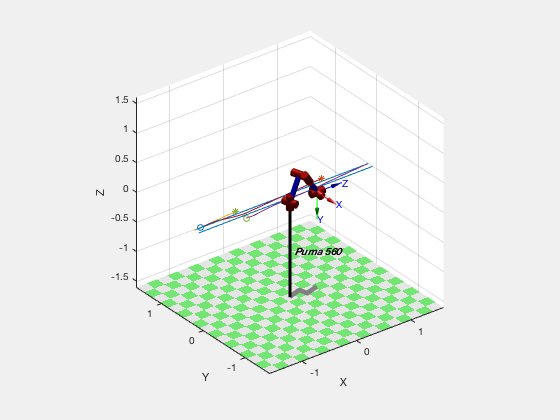

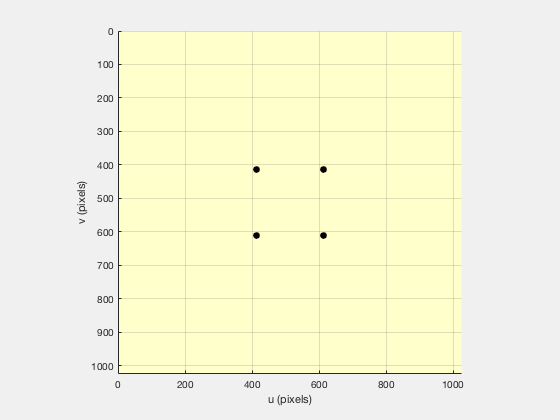

sl_arm_ibvs

r = sim('sl_arm_ibvs')


q = squeeze(r.find('yout').signals(1).values)';

Undefined variable "out" or class "out.find".


about(q)

## 16.5.1 Holonomic Mobile Robot


cam = CentralCamera('default', 'focal', 0.002);

V_T_C = SE3(0.2, 0.1, 0.3)*SE3.Rx(-pi/4);

P = [0 0; 1 -1; 2 2]

sl_omni_vs

r = sim('sl_omni_vs')



## 16.5.2 Nonholonomic Mobile Robot

sl_drivepose_vs

r = sim('sl_ibvs')


## 16.6 Application: Aerial Robot

sl_quadrotor_vs

sim('sl_quadrotor_vs')
